# Numerical Methods for Optimization and Control Theory

## Assignment 1 - Daniel Kuknyo

Tasks assigned: 2, 5, 7, 13

## 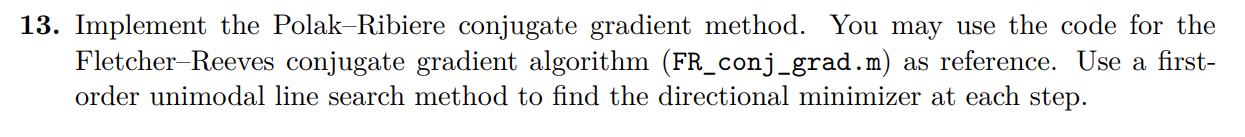

My first-order unimodal line search method of choice is the Bisection algorithm. Below is a demonstration on our simple unimodal function.

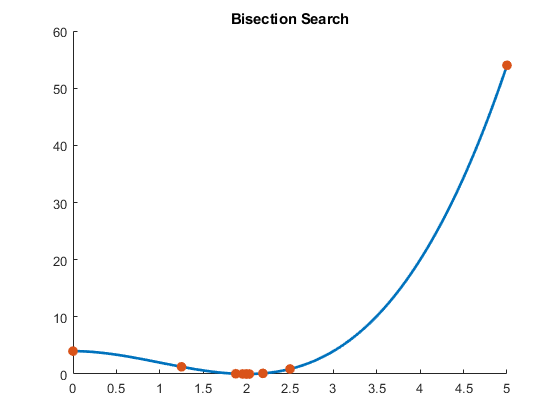

f = @(x) x.^3 - 3*x.^2 + 4;
df = @(x) 3*x.^2 - 6*x;
ddf = @(x) 6*x - 6;

plot_unimodal_method(@bisection_search, f, df, ddf, 20, 4, 0, 5, 256, 'Bisection Search');

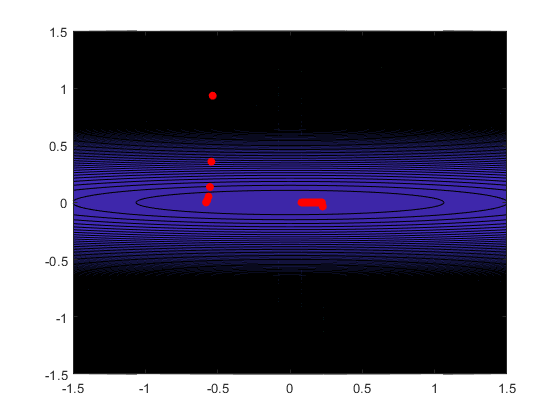

% Ideal convex paraboloid
a = 0.01;
f = @(x) a .* x(1).^2 + x(2).^2;
df = @(x) [2. * a .* x(1); 2 .* x(2)];
ddf=@(x) [2 .* a 0; 0 2];

plot_polak_ribiere(@PR_conj_grad, f, df, ddf, 100, ...
    [-0.5342, 0.9342], -1.5, 1.5, -1.5, 1.5, 256);

### Functions

function x = plot_unimodal_method(G,f,df,ddf,testpts,startpt,a,b,res,ptitle)
    X = linspace(a,b,res);
    Y = f(X);
    x = [a b];
    
    for k = 1:testpts
        x_k = G(f,df,ddf,startpt,a,b,k);
        x = [x x_k];
    end
    
    figure; hold on;
    plot(X, Y, 'LineWidth', 2);
    plot(x, f(x), '.', 'MarkerFaceColor', 'auto', 'MarkerSize', 25);
    title(ptitle);
    hold off;
end

function [ x ] = plot_polak_ribiere(G,f,df,ddf,testpts,startpt,a,b,c,d,res)
    X = linspace(a,b,res);
    Y = linspace(c,d,res);
    [X,Y] = meshgrid(X,Y);
    Z = zeros(res,res);
    for i=1:res
        for j=1:res
            Z(i,j) = f([X(i,j),Y(i,j)]);
        end
    end

    x = zeros(testpts+1,2);
    x(1,:) = startpt;
    for k=1:testpts
        x(k+1,:) = G(f,df,ddf,x(1,:)',k);
    end
    
    contourf(X,Y,Z,200); hold on
    scatter(x(:,1),x(:,2),'r','filled');
    hold off;
end

% A first-order bisection search implementation
function [ x ] = bisection_search(f,df,~,~,a,b,iter) 
    delta = [a b];
    eps = 0.000001;
    x = [];
    
    for i = 1:iter
        x_k = (delta(1) + delta(2)) / 2;
        dfx_k = df(x_k);
        
        if(logical(abs(dfx_k) <= eps))
            x = x_k;    
        elseif(i>iter-1)
            x = x_k;
        elseif(dfx_k > 0)
            delta = [delta(1) x_k];
        elseif(dfx_k < 0)
            delta = [x_k delta(2)];
        end
    end
end

function [ x ] = PR_conj_grad(f,df,~,x0,iter)
    eps=1e-12; % treshold for stability and directional minimization
    
    for k=1:iter
        x=x0;
        d = -df(x); % Steepest descent
        p = d;
        for i=1:size(x)
            
            if norm(d)>eps % avoid too small gradient
                % Directional minimization
                fdir = @(t) f(x + t*p);
                dfdir = @(t) df(x + t*p);
                
                tmax=eps;
                while fdir(tmax) < fdir(tmax/2)
                    tmax=2*tmax; % expand until has at least one minimizer
                end
                
                % Directional minimization
                gamma = bisection_search(fdir, dfdir, 0, 0, 0, ...
                    tmax, log(eps/tmax)/log(2/3));
                
                % Go to the next point using the P-R-P formula
                x = x + gamma * p;
                beta = 1 / (d' * d);
                d_m = d;
                d = -df(x); % step
                
                beta = beta * ((d - d_m)' * d);
                p = d+beta*p;
                
                % If p is not a descent direction
                if 0 > p'*d
                    p = -p;
                end
            end
        end
        x0=x;
    end
end